%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                                         %
%                   LAB 1 - ASEN 2004                     %
%                 Glider Wing Analysis                    %
%                                                         %
%                                                         %
%        This script takes in 2-dimensional data for      %
%            a foam glider and calculates                 %
%        the 3-dimensional whole aircraft drag polar,     %
%        as well as performance analysis calculations     %
%       for maximum glide range, maximum powered range,   %
%             and maximum powered endurance.              %
%                                                         %
%                  Created: 02/03/2021                    %
%               Last Modified: 02/23/2021                 %
%                                                         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Set Environment

clear
clc

## Set Variables

% Given Variables
Re = 160000;                            % Glider Reynold's Number [dimensionless]
e0 = 0.601;                             % Glider Oswald's Efficiency 
C_fe = 0.003;                           % Civil Transport Skin Friction Coefficient
h = 7;                                  % Glider launch altitude [m]
rho = 1.0581;                           % Air density STD ATM for Boulder [kg/m^3]
mu = 1.74*(10^-5);                      % Viscosity [kg/m s]
W_payload = 1.5696;                     % GoPro Camera Weight [N]
wConv = 0.295*9.81;                     % Weight Conversion Constant [N / m^2]

## Set User Variables

% FUSELAGE DIMENSIONS
d = 0.075;                              % Glider Fuselage Width [m]
L = 0.45;                               % Glider Fuselage Length [m]

% MAIN WING
b = 1;                                  % Glider Main Wing Span [m]
w_c_r = 0.71;                          % Glider Main Wing Root Chord [m]
w_c_t = w_c_r;                          % Glider Main Wing Tip Chord  [m]
w_lambda = w_c_t/w_c_r;                 % Glider Main Wing Taper Ratio [dimensionless]

x_le = 0.2;                             % Location of the main wing leading edge in x direction [m]

% HORIZONTAL STABILIZER
e_b = 0.25;                             % Glider Elevator Span [m]
e_c_r = 0.05325;                        % Glider Elevator Root Chord [m]
e_c_t = 0.026625;                       % Glider Elevator Tip Chord  [m]
e_lambda = e_c_t/e_c_r;                 % Glider Elevator Taper Ratio [dimensionless]

% VERTICAL STABILIZER
v_b = 0.1;                              % Glider Vertical Stabilizer Span [m]
v_c_r = 0.071;                          % Glider Vertical Stabilizer Root Chord [m]
v_c_t = 0.05325;                        % Glider Vertical Stabilizer Tip Chord  [m]
v_lambda = v_c_t/v_c_r;                 % Glider Vertical Stabilizer Taper Ratio [dimensionless]

x_v_le = L - v_c_r;                     % Location of the vertical stab leading edge in the x direction [m]

% PAYLOAD
payload_h = 0.039;                      % Payload Height [m]
payload_w = 0.0593;                     % Payload Width [m]
payload_l = 0.0698;                     % Payload Length [m]
x_payload_f = 0.3;                      % The location of the payload front face 
                                        %   with respect to the nose cone tip [m]
% BALLAST
W_ballast = 3;                          % Glider Ballast Weight [N]
ballast_h = 0.03;                       % Ballast Height [m]
ballast_w = 0.03;                       % Ballast Width [m]
ballast_l = 0.03;                       % Ballast Length [m]
x_ballast_f = 0;                        % The location of the ballast front face 
                                        %   with respect to the nose cone tip [m]
% REYNOLD'S
v_flow = 12;                            % Velocity of Airflow [m/s] - Currently the max of vel. requirment
reynolds_crit = 5*(10^5);               % Critical Reynold's Number for a flat plate

## Define Surface Areas

S_wing = (b/2)*w_c_r*(1+w_lambda);      % Glider Main Wing Planform Area [m^2]
S_ref = S_wing;                         % Glider Reference Planform Area [m^2]
S_vert = (v_b/2)*v_c_r*(1+v_lambda);    % Glider Vertical Planform Area [m^2]
S_elev = (e_b/2)*e_c_r*(1+e_lambda);    % Glider Horizontal Stabilizer Planform Area [m^2]
S_fuselage = (4*L*d);                   % Glider Fuselage Wet Surface Area

## Define Glider Variables

AR = (b^2)/(S_wing);                                        % Glider Aspect Ratio [dimensionless]
S_wet = S_fuselage + (2*S_wing) + (2*S_elev) + (2*S_vert);  % Glider Wet Planform Area [m^2]
W_glider = 0.295*9.81*S_wet;                                % Glider Weight [N]
W = W_glider + W_payload + W_ballast;                       % Total Glider Weight [N]
W_wing = 0.295*9.91*S_ref;                                  % Wing Weight [N]

% Calculate Mean Aerodynamic Chord for main wing
c_bar = (2/3)*w_c_r*((1+w_lambda+(w_lambda^2))/(1+w_lambda));

% Calculate Mean Aerodynamic Chord for horizontal stab.
c_e_bar = (2/3)*e_c_r*((1+e_lambda+(e_lambda^2))/(1+e_lambda));

% Calculate Mean Aerodynamic Chord for vertical stab.
c_v_bar = (2/3)*v_c_r*((1+v_lambda+(v_lambda^2))/(1+v_lambda));

% Calculate Reynold's Number for Tapered Main Wing
reynolds_c_bar = (rho*(v_flow)*c_bar)/mu;

% Calculate x critical (the point where flow goes from laminar to turbulent)
x_cr = (reynolds_crit*mu)/(rho*v_flow);
x_c = x_cr/w_c_r;

% Create the Variable Array for the Tempest
vars = [AR, Re, e0, S_wet, S_ref, C_fe, d, b];

% Appendix Two - Flat Plate Approximation Tables
% [AOA C_l C_d C_M]
dataAct = [-15 -0.6  0.2  0.09;
         -14 -0.6  0.2  0.09; 
         -13 -0.7  0.2  0.09;
         -12 -0.8  0.19 0.085;
         -11 -0.8  0.18 0.08;
         -10 -0.75 0.14 0.07;
         -9  -0.85 0.12 0.055;
         -8  -0.8  0.1  0.04;
         -7  -0.7  0.08 0.03;
         -6  -0.6  0.06 0;
         -5  -0.5  0.04 -0.01;
         -4  -0.4  0.02 -0.005;
         -3  -0.3  0.01 0;
         -2  -0.2  0.005 0;
         -1  -0.1  0.005 0;
         0   0     0     0;
         1   0.1   0     0;
         2   0.2   0.005 0;
         3   0.3   0.01  0;
         4   0.4   0.02  0;
         5   0.45  0.04  0;
         6   0.6   0.06  0;
         7   0.7   0.08  -0.01;
         8   0.8   0.12  -0.03;
         9   0.8   0.13  -0.06;
         10  0.8   0.14  -0.08;
         11  0.8   0.16  -0.1;
         12  0.8   0.18  -0.1;
         13  0.8   0.19  -0.1;
         14  0.74  0.21  -0.1;
         15  0.74  0.22  -0.1;
         16  0.74  0.24  -0.1;
         17  0.73  0.25  -0.1;
         18  0.73  0.26  -0.1;
         19  0.7   0.28  -0.1;
         20  0.7   0.3   -0.1;];

## Calculate all the center of gravities in the x direction

% cg_fuselage - the x location of the fuselage's center of gravity with
% respect to its nose cone tip
cg_fuselage = (L/2);

% x_cg_fuselage - the x location of the fuselage's center of gravity with
% respect to the leading edge of the main wing
x_cg_fuselage = cg_fuselage - x_le;

% x_ac_w - the x location of the main wing mean aerodynamic center from the 
% leading edge of the main wing
x_ac_w = 0.25*c_bar;

% x_cg_wing - the x location of the main wing's center of gravity with
% respect to it's leading edge
x_cg_wing = 0.5*c_bar;

% cg_vertical - the x location of the vertical stab. center of gravity with respect to it's
% leading edge
cg_vertical = 0.5*c_v_bar;

% x_cg_vertical - the x location of the vertical stab. center of gravity
% with respect to the leading edge of the main wing
x_cg_vertical = (x_v_le + cg_vertical) - x_le;

% x_ac_v - the x location of the vertical stab mean aerodynamic center from the 
% leading edge of the main wing
x_ac_v = (x_v_le + (0.25*c_v_bar)) - x_le;

% cg_horizontal - the x location of the horizontal stab. center of gravity with respect to
% it's leading edge
cg_horizontal = 0.5*c_e_bar;

% x_cg_horizontal - the x location of the horizontal stab. center of
% gravity with respect to the main wing leading edge
x_e_le = x_v_le+(v_c_r - v_c_t);           % The start of the horizontal stab leading edge [m] 
                                           % assuming T-tail where leading edge starts at leading
                                           % edge of vertical stab tip
x_cg_horizontal = (x_e_le + cg_horizontal) - x_le;

% x_ac_h - the x location of the horizontal stab mean aerodynamic center from the 
% leading edge of the main wing
x_ac_h = (x_e_le + (0.25*c_e_bar)) - x_le;

% cg_payload - the x location of the payload's center of gravity with
% respect to it's front face
cg_payload  = (payload_l/2);

% x_cg_payload - the x location of the payload's center of gravity with
% respect to the main win leading edge
x_cg_payload = (x_payload_f + cg_payload) - x_le;

% cg_ballast - the x location of the ballast's center of gravity with
% respect to it's front face
cg_ballast  = (ballast_l/2);

% x_cg_ballast - the x location of the ballast's center of gravity with
% respect to the main win leading edge
x_cg_ballast = (x_ballast_f + cg_ballast) - x_le;

% Declare and Define remaining weights
W_fuselage = wConv*S_fuselage;
W_horz_stab = wConv*2*S_elev;
W_vert_stab = wConv*2*S_vert;

% x_cg - the location of the aircraft cg at an x distance from the leading
% edge of the main wing (The sum of all the cg's in the x direction divided by their total weight)
x_cg = ((W_fuselage*x_cg_fuselage) + ...
        (W_horz_stab*x_cg_horizontal) + ...
        (W_vert_stab*x_cg_vertical) + ...
        (W_payload*x_cg_payload) + ...
        (W_ballast*x_cg_ballast)) / W;

## Lateral Directional Stability

% Lateral Stability Equation
V_v = (S_vert*(x_ac_v - x_cg)) / (S_ref * b);

## Longitudinal Stability

% Longitudinal Stability Equation
V_H = (S_elev*(x_ac_h - x_cg)) / (S_ref * w_c_r);

## Calculations

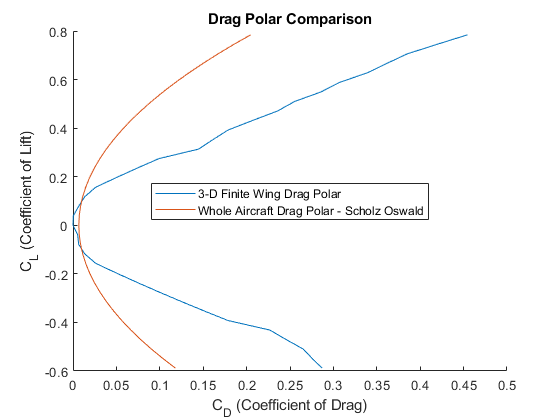

% Calculate the C_L and C_D 
[C_L,C_D_w] = finiteWingLift(dataAct,vars,0,6);

% Calculate the Whole Drag Polar using labDocument method
eLabDocument = labDocument(vars);
[C_D_labDocument,C_D_0_labDocument] = wholeAircraftDragPolar(C_L, C_D_w, eLabDocument, vars);

% Calculate the Whole Drag Polar using MNita_DScholz method
eMNita_DScholz = MNita_DScholz(C_D_w, 0.9, vars);
[C_D_MNita_DScholz,C_D_0_MNita_DScholz] = wholeAircraftDragPolar(C_L, C_D_w, eMNita_DScholz, vars);

% Calculate the Whole Drag Polar using Oberts method
eOberts = oberts(vars);
[C_D_Oberts,C_D_0_Oberts] = wholeAircraftDragPolar(C_L, C_D_w, eOberts, vars);

% Calculate the Whole Drag Polar using Kroo's method
eKroos = kroos(C_D_w, 0.9, vars);
[C_D_Kroos,C_D_0_Kroos] = wholeAircraftDragPolar(C_L, C_D_w, eKroos, vars);

% Combine all Oswald's factors and C_Ds in one array for performance calcs
e0 = [eKroos,eLabDocument,eMNita_DScholz,eOberts];
C_D = [C_D_Kroos,C_D_labDocument,C_D_MNita_DScholz,C_D_Oberts];
C_D_0 = mean([C_D_0_Oberts,C_D_0_labDocument,C_D_0_MNita_DScholz,C_D_0_Kroos]);

% figure;
% hold on
% plot(data(:,1), C_L);
% plot(data(:,1), data(:,2));
% plot(dataAct(:,1), dataAct(:,2),'-.r*');
% title('Lift Curve Comparsion: Tempest UAS');
% xlabel('α (Angle of Attack)');
% ylabel('C_L (Coefficient of Lift)');
% legend('3-D Finite Wing Curve', '2-D Airfoil Curve', 'Tempest CFD Drag Polar', 'Location', 'best');
% hold off

figure;
hold on
%plot(dataAct(:,3), dataAct(:,2));
plot(C_D_w,C_L);
plot(C_D_MNita_DScholz,C_L);
title('Drag Polar Comparison');
ylabel('C_L (Coefficient of Lift)');
xlabel('C_D (Coefficient of Drag)');
legend('3-D Finite Wing Drag Polar','Whole Aircraft Drag Polar - Scholz Oswald','Location','best');
hold off

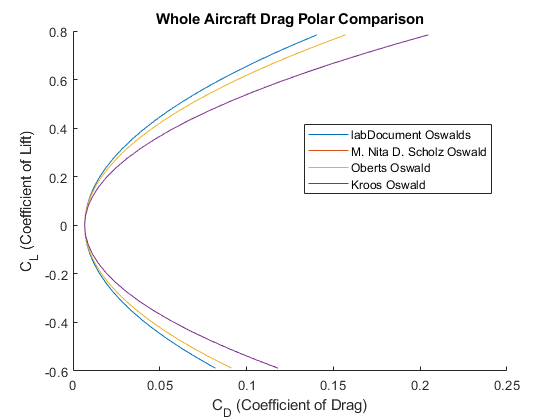


figure;
hold on
plot(C_D_labDocument,C_L);
plot(C_D_MNita_DScholz,C_L);
plot(C_D_Oberts,C_L);
plot(C_D_Kroos,C_L);
%plot(dataAct(:,3),dataAct(:,2));
title('Whole Aircraft Drag Polar Comparison');
xlabel('C_D (Coefficient of Drag)');
ylabel('C_L (Coefficient of Lift)');
legend('labDocument Oswalds', ...
       'M. Nita D. Scholz Oswald', ...
       'Oberts Oswald', ...
       'Kroos Oswald', 'Location', 'best');
%    'Glider CFD Drag Polar'
hold off

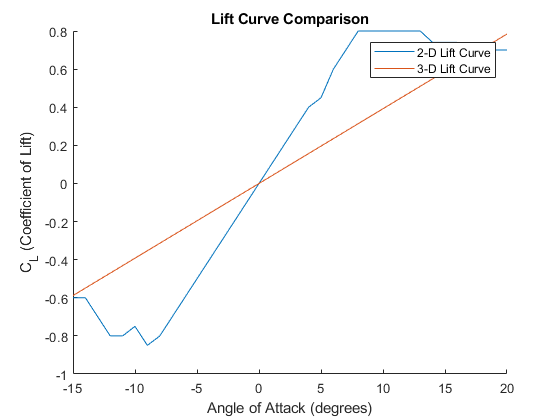


figure;
hold on
plot(dataAct(:,1),dataAct(:,2));
plot(dataAct(:,1),C_L);
title('Lift Curve Comparison');
xlabel('Angle of Attack (degrees)');
ylabel('C_L (Coefficient of Lift)');
legend('2-D Lift Curve','3-D Lift Curve');
hold off

## Performace Flight Conditions Calculations

% Define empty arrays for glide LDmaxes
Glide_LDMax = zeros(1,4);

% Define empty arrays for max glide ranges, endurances, angles and velocities
Glide_Range_V = zeros(1,4);
Glide_Endur_V = zeros(1,4);
Glide_Theta = zeros(1,4);
Glide_Range = zeros(1,4);
Glide_Endurance = zeros(1,4);
Glide_C_L_Max = zeros(1,4);
Glide_C_L_Pmin = zeros(1,4);

% performance calculations for each Oswald's using calculated data
for i=1:4
   [Glide_LDMax(i),Glide_C_L_Max(i),Glide_C_L_Pmin(i),...
       Glide_Range_V(i),Glide_Endur_V(i),Glide_Theta(i),...
       Glide_Range(i),Glide_Endurance(i)] = ...
       glide(h,C_D(:,i),C_L,e0(i),...
       AR,rho,W,S_ref,C_D_0); 
end

% performance calculations for avg Oswald's using given data
[FiniteGlide_LDMax,FiniteGlide_CLMax,FiniteGlide_CLPmin,...
    FiniteGlide_Range_V,FiniteGlide_Endur_V,...
    FiniteGlide_Theta,FiniteGlide_Range,FiniteEndurance] = ...
    glide(h,dataAct(:,3),dataAct(:,2),mean(e0),...
    AR,rho,W,S_ref,C_D_0);

% must have 10 degree dihedral to be approximately neutral spiral
B = ((x_ac_v - x_cg)./b) .* (10./mean(Glide_C_L_Max));

## Print results out to terminal

Results = table([Glide_LDMax';mean(Glide_LDMax)],...
    [Glide_C_L_Max';mean(Glide_C_L_Max)],...
    [Glide_C_L_Pmin';mean(Glide_C_L_Pmin)],...
    [Glide_Range_V';mean(Glide_Range_V)],...
    [Glide_Endur_V';mean(Glide_Endur_V)],...
    [Glide_Theta';mean(Glide_Theta)],...
    [Glide_Range';mean(Glide_Range)],...
    [Glide_Endurance';mean(Glide_Endurance)],...
    'RowNames',{'Kroos','Lab Doc','Scholz','Oberts','Mean'},...
    'VariableNames',{'Glide LDMax','Glide C_L Max',...
    'Glide C_L for Min Power','Glide Max Range Velocity (m/s)',...
    'Glide Max Endurance Velocity (m/s)',...
    'Glide AoA (deg)','Max Glide Range (m)','Max Glide Endurance (s)'})

Results = 5×8 table
               Glide LDMax    Glide C_L Max    Glide C_L for Min Power    Glide Max Range Velocity (m/s)    Glide Max Endurance Velocity (m/s)    Glide AoA (deg)    Max Glide Range (m)    Max Glide Endurance (s)
               ___________    _____________    _______________________    ______________________________    __________________________________    _______________    ___________________    _______________________

    Kroos        10.725          0.15686               0.25004                        12.971                              9.8508                      5.3271               75.072                   6.8543         
    Lab Doc       13.01          0.19


fprintf('\nC_D_0 = %f \n',C_D_0);


C_D_0 = 0.006707 


fprintf('W_Total = %f N \n',W);

W_Total = 9.163438 N 


fprintf('Center of gravity: %f m from leading edge of wing\n',x_cg);

Center of gravity: -0.034197 m from leading edge of wing


fprintf('Wing loading (W_TO/S_ref): %f N/m^2\n',W/S_ref);

Wing loading (W_TO/S_ref): 12.906251 N/m^2


## Functions

% finiteWingLift
%
% Function that calculates the 3D finite wing 3D lift coefficient and 3D wing
% drag polar
%
% @param data   The table data that includes the AOA, C_l, and the C_d in
%                   that order.
% @param vars   Needed variables on a per aircraft process like Aspect ratio
%                   and oswald's number
% @param aoa_one The lowest AOA to evaluate at
% @param aoa_two The highest AOA to evaluate at
%

function [C_L,C_D_wing] = finiteWingLift(data,vars,aoa_one,aoa_two)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    
    % Get the slope of the linear portion of the 2D lift curve from airfoil data
    linearFit = polyfit(data(data(data(:,1)<aoa_two,1)>aoa_one,1),data(data(data(:,1)<aoa_two,1)>aoa_one,2),1);
    
    % Set the slope of 2D airfoil curve as a_0 according to convention
    a_0 = linearFit(1);
    
    % Define the Span Efficiency factor
    e = 0.9;
    
    % Define a the lift curve slope
    a = a_0/(1+((57.3*a_0)/(pi*e*AR)));
    
    % Get the AOA where the C_L equal 0
    %alpha_aoa_0 = interp1(data(:,2),data(:,1),0,'linear','extrap'); % FOR ANYTHING ELSE
    alpha_aoa_0 = data(find(data(:,2)==0),1); % FOR FLAT PLATE
    
    % Calculate C_L for all AOA
    C_L = a*(data(:,1)-alpha_aoa_0);
    
    % Calculate C_D_wing
    C_D_wing = data(:,3) + (C_L.^2)./(pi*e*AR);
end

% wholeAircraftDragPolar
%
% Function that calculates the whole aircraft drag polar
%
% @param C_L        The calculated C_L values for a specific aircraft
% @param C_D_Wing   The calculated C_D_wing values for a specific aircraft
% @param e_0        The Oswald's Efficiency number for a specific model
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function [C_D,C_D_0] = wholeAircraftDragPolar(C_L, C_D_wing, e_0, vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    S_wet = vars(4);    % Wet Planform Area
    S_ref = vars(5);    % Reference Planfrom Area
    C_f_e = vars(6);    % Coefficient of Skin Friction
    
    % Calculate K1
    k_1 = 1/(pi*e_0*AR);
    
    % Calculate C_D_min
    C_D_min = C_f_e * (S_wet/S_ref);
    
    % Calculate C_L_minD
    xmin = find(C_D_wing==min(C_D_wing));
    C_L_minD = C_L(xmin);
    
    % Calculate the Whole Aircraft Drag Polar
    C_D = C_D_min + (k_1*((C_L-C_L_minD).^2));
    
    % Calculate C_D_0
    C_D_0 = C_D_min + (k_1*(C_L_minD^2));
end

## Oswald's Efficiency Calculation Functions

% labDocument
%
% Function that Oswald's number using the Lab Document method equation 12
%
% @param vars       Needed variables on a per aircraft process like Aspect Ratio
%                       and oswald's number
%
function e = labDocument(vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    
    % Calculate Oswald's factor
    e = (1.78*(1-(0.045*(AR^0.68)))) - 0.64;
end

% MNita_DScholz
%
% Function that Oswald's number using M. Nita D. Scholz method
%
% @param C_D        The Coefficient of Drag for Finite Wing
% @param e          The Span Efficieny Factor
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function e = MNita_DScholz(C_D, e, vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    d = vars(7);        % Fuselage Diameter
    b = vars(8);        % Aircraft Wing Span
    K_e_m = 1;          % 1 because aircrafts are subsonic
    
    % Define k_e_f
    k_e_f = 1 - (2*((d/b)^2));
    
    % Find C_D_0
    C_D_0 = C_D(6); % AOA of 0 degrees
    
    % Define Q
    Q = 1 / (e*k_e_f);
    
    % Define P
    P = 0.38*C_D_0;
    
    % Calculate Oswald's factor
    e = K_e_m/(Q+(P*pi*AR));
end

% oberts
%
% Function that Oswald's number using Obert's method
%
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function e = oberts(vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio

    % Calculate Oswald's factor
    e = 1/(1.05+(0.007*pi*AR));
end

% kroos
%
% Function that Oswald's number using Kroo's method
%
% @param C_D        The Coefficient of Drag for Finite Wing
% @param e          The Span Efficieny Factor
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function e = kroos(C_D, e, vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    d = vars(7);        % Fuselage Diameter
    b = vars(8);        % Aircraft Wing Span
    K = 0.38;           % WTF is K?
    
    % Define u
    u = e;
    
    % Define S
    s = 1 - (2*((d/b)^2));
    
    % Find C_D_0
    C_D_0 = C_D(6); % AOA of 0 degrees
    
    % Define P
    P = K*C_D_0;
    
    % Calculate Oswald's Factor
    e = 1/((1/(u*s))+(P*pi*AR));
end

## Performance Calculations

glide

% Calculates L/Dmax, ranges and velocities for max endurance and max range
% glide

function [LDmax,C_L_max,C_L_endur,V_range,V_endur,theta_range,R_max,endurance] = glide(h,C_D,C_L,e0,AR,rho,W,S,C_D_0)
% max endurance: at 3CD0 = kCL^2
% max range: at CD0 = kCL^2

    % define k
    k = 1/(AR*pi*e0);
    C_L_range = sqrt(C_D_0/k);
    C_L_endur = sqrt(3*C_D_0/k);
    [LDmax,idx] = max(C_L./C_D);
    C_L_max = C_L(idx);
    [~,idx2] = min(abs(C_L-C_L_endur));
    R_max = h*(C_L(idx)/C_D(idx));
    R_endur = h*(C_L(idx2)/C_D(idx2));
    
    % calculate glide angle
    theta_range = atan(h/R_max);
    theta_endur = atan(h/R_endur);
    
    % calculate velocities for max range and max endurance
    V_range = sqrt((2*cos(theta_range)*W)/(rho*C_L_range*S));
    V_endur = sqrt((2*cos(theta_endur)*W)/(rho*C_L_endur*S));
    sink_rate = V_endur*(sin(theta_endur));
    endurance = h/sink_rate;
    
    theta_range = rad2deg(theta_range);
    theta_endur = rad2deg(theta_endur);
end